%% ------------------------------------------------------------------------
% ------------ Compress Audio Signal --------------------------------------
% -------------------------------------------------------------------------
% Using dynamic range compression to attenuate the volume of loud sounds. 
%
% in this live script Matlab file, the 'compressor' function from matlab audio
% system toolbox is used to apply compression on input signal.
%% ------------------------------------------------------------------------
% ------------ Paths Configuration ----------------------------------------
% -------------------------------------------------------------------------
% Here, the paths of all subfolders for generating the ... are added to the
% Workspace of MATLAB.
close all         % Closing previous figures.
clc               % Clean parameteres from command window
%
% ConfigPath1;      % Configuring the paths (first version)
 ConfigPath2;    % Configuring the paths (second version)

ConfigPath: Paths added


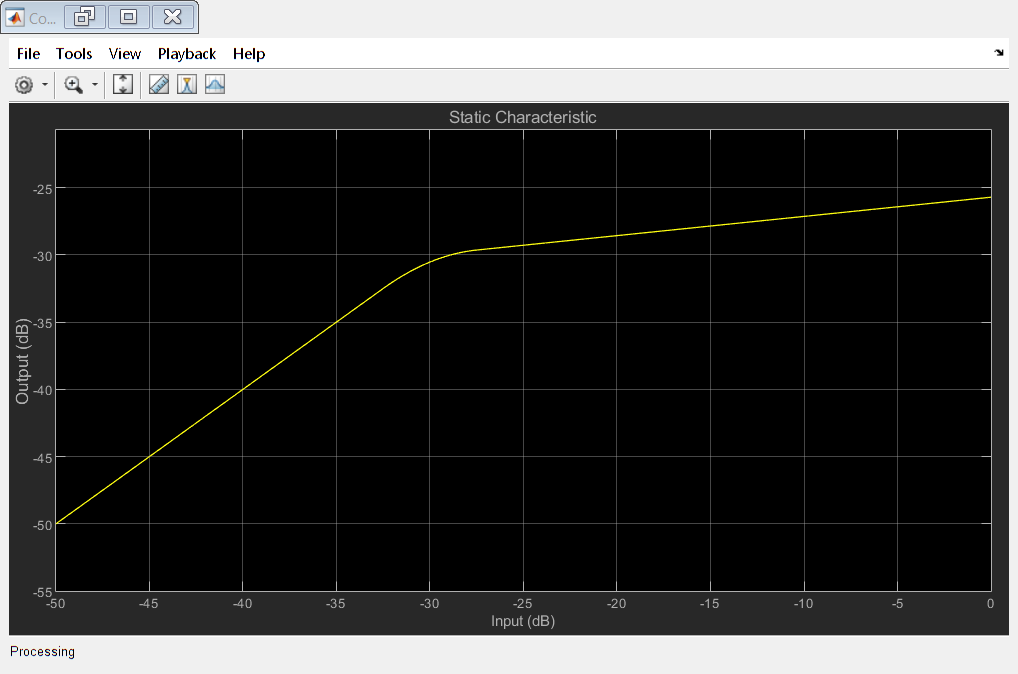

%
%% ------------------------------------------------------------------------
% ------------ Compression Procedure --------------------------------------
% -------------------------------------------------------------------------
% Set up the dsp.AudioFileReader and audioDeviceWriter System objects™.
%frameLength = 1024;
fileReader = dsp.AudioFileReader( ...
    'Filename','noisy.wav', ...
    'SamplesPerFrame',1024);
deviceWriter = audioDeviceWriter( ...
    'SampleRate',fileReader.SampleRate);
%% ------------------------------------------------------------------------
% Set up the compressor to have a threshold of -30 dB, a ratio of 7, and a 
% knee width of 5 dB. Use the sample rate of your audio file reader.
dRC = compressor(-30,7,...
    'KneeWidth',5,...
    'SampleRate',fileReader.SampleRate);
%% ------------------------------------------------------------------------
% Visualize the compression static characteristic.
visualize(dRC)
% Set up the scope to visualize the original audio signal, the compressed 
% audio signal, and the applied compressor gain.
scope = dsp.TimeScope( ...
    'SampleRate',fileReader.SampleRate, ...
    'TimeSpan',14, ...
    'BufferLength',44100*15, ...
    'YLimits',[-1,1], ...
    'TimeSpanOverrunAction','Scroll', ...
    'ShowGrid',true, ...
    'LayoutDimensions',[2,1], ...
    'NumInputPorts',2, ...
    'Title', ...
    ['Original vs. Compressed Audio (top)' ...
    ' and Compressor Gain in dB (bottom)']);

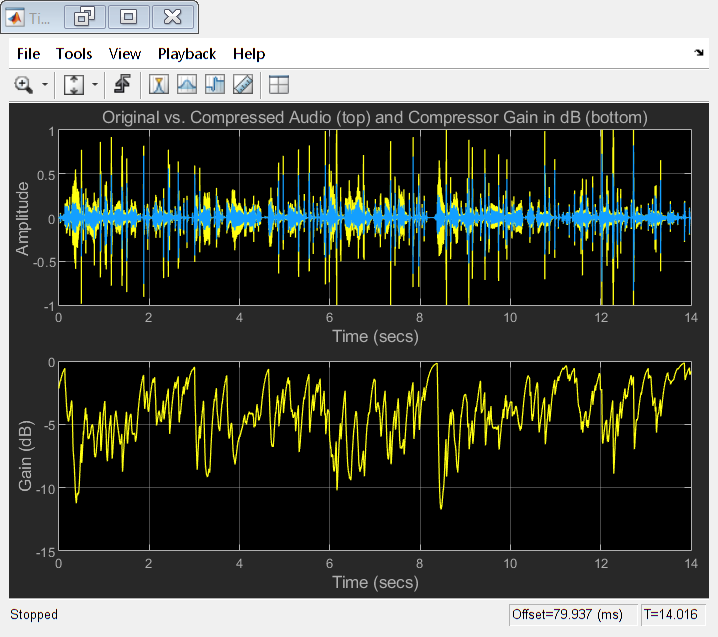

scope.ActiveDisplay = 2;
scope.YLimits = [-15,0];
scope.YLabel = 'Gain (dB)';
% Play the processed audio and visualize it on the scope.
while ~isDone(fileReader)
    x = fileReader();
    [y,g] = dRC(x);
    deviceWriter(y);
    scope([x(:,1),y(:,1)],g(:,1))
end

release(dRC)
release(deviceWriter)
release(scope)

%% ------------------------------------------------------------------------
% ------------ Creating the compressed signal File ------------------------
% -------------------------------------------------------------------------
audiowrite('Results\Compressed Signal\CompressedSignal2.wav',y,16000); % the 'CompressedSignal2.wav' File
                                   %(which is the compressed output signal)
                                   % will be saved in 'Using Matlab Audio System toolbox\Matlab Files\Results\Compressed Signal'. 